clear all;
path_time= readtable('traj_opt_09.csv');

path_dist= readtable('traj_shortest.csv');

path_center= readtable('track_smooth.csv');


s_time= readtable('length_opt.csv');

s_dist= readtable('length_shortest.csv');


track_outer=readtable('london_outer.csv');

track_inner=readtable('london_inner.csv');


curv_time= readtable('kappa_opt_09.csv');

curv_dist= readtable('kappa_shortest.csv');

curv_center= readtable('kappa_center.csv');

weight= 0.7;
path_opt= weight.*[path_time.x_Traj_x, path_time.traj_y]+ (1-weight).*[path_dist.x_Traj_x, path_dist.traj_y];


path_opt_temp= path_opt(2:end,:);
dxy= path_opt_temp- path_opt(1:end-1,:);
ds_cum=cumsum(sqrt(dxy(:,1).^2+ dxy(:,2).^2));
s_opt= ds_cum(end);
s_time_cum= cumsum(s_time.x_S_opt);
s_dist_cum= cumsum(s_dist.x_S_opt);
s_min_time= s_time_cum(end);
s_min_dist= s_dist_cum(end);

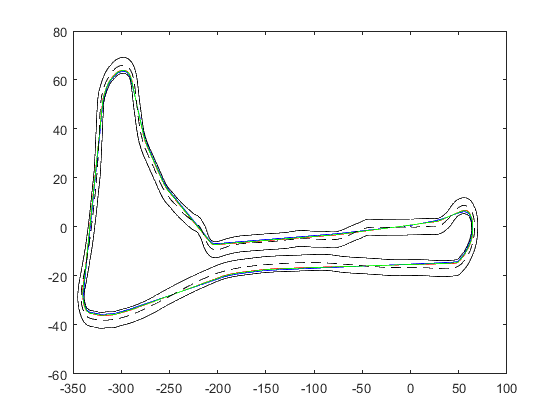

close all;
figure();
plot(path_time.x_Traj_x, path_time.traj_y, "Color", "red");
hold on;
plot(path_dist.x_Traj_x, path_dist.traj_y, "Color", "blue");
hold on;
plot(path_opt(:,1), path_opt(:,2), "Color", "green");
hold on;
plot(path_center.x_Track_x, path_center.track_y, "Color", "black", "LineStyle","--");
hold on;
plot(track_inner.x_X, track_inner.y, "Color", "black")
hold on;
plot(track_outer.x_X, track_outer.y, "Color", "black")
hold off;

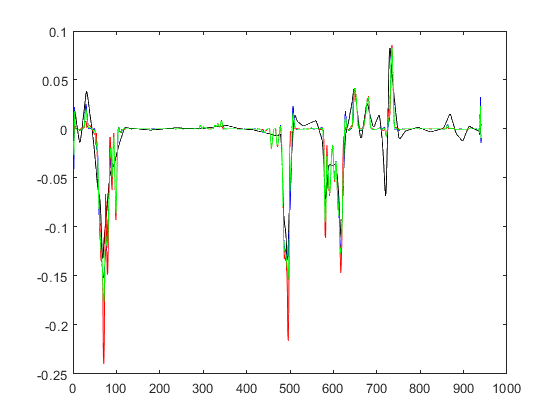

figure();
plot(curv_center.x_Kappa_center, "black");
hold on;
plot(curv_time.x_Kappa_opt, "blue");
hold on;
plot(curv_dist.x_Kappa_opt, "red");
hold on;
plot(weight.*curv_time.x_Kappa_opt+ (1-weight).*curv_dist.x_Kappa_opt, "green");
hold off;